# Control de sistemas biológicos TP N°1 PROBLEMA 2 (dado)

A continuación se resuelve el ejercicio 3 de la práctica N°1 (producción bacterial de bioplástico).

El modelo a controlar es el siguiente:

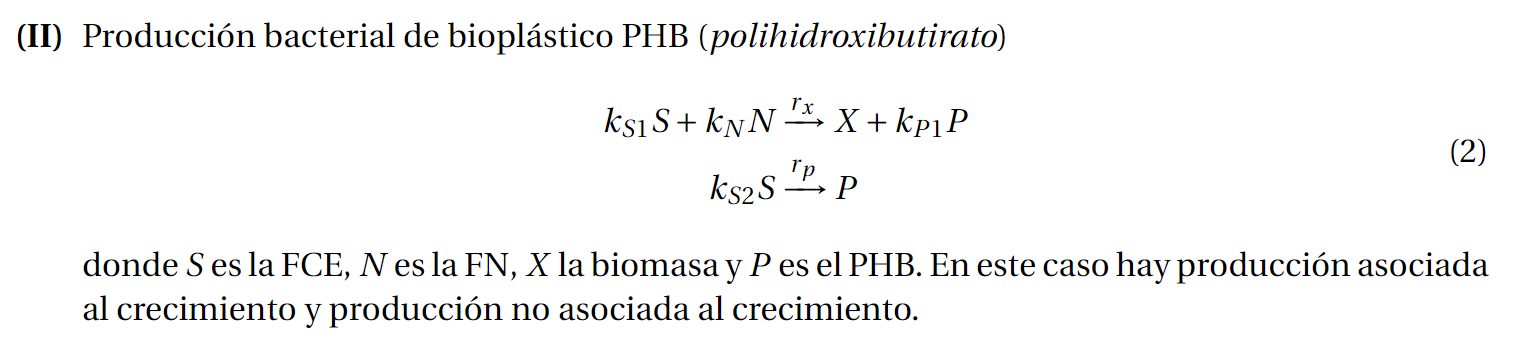

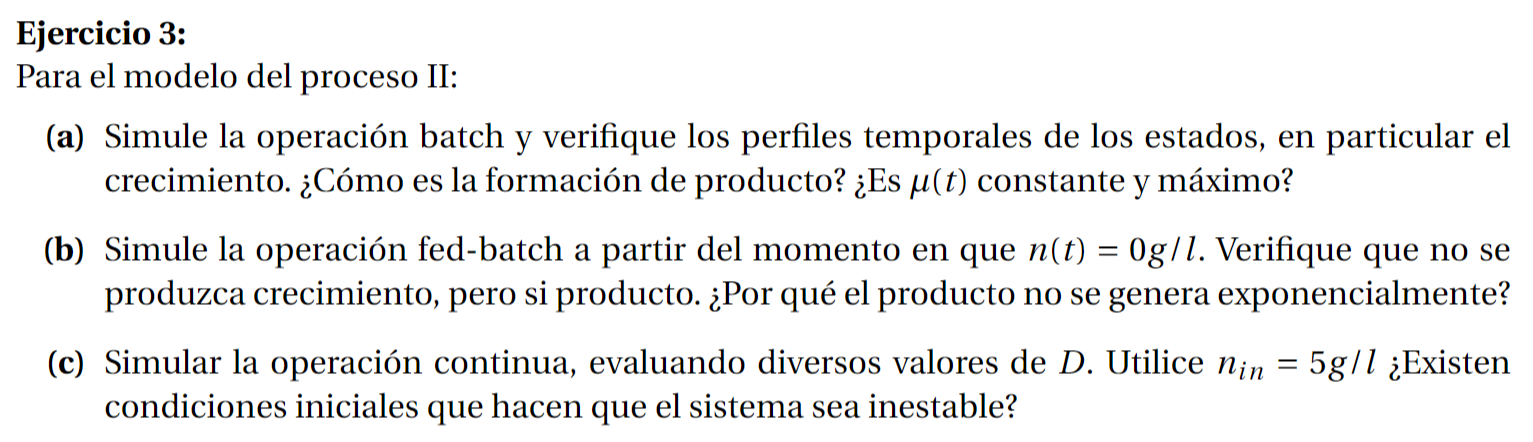

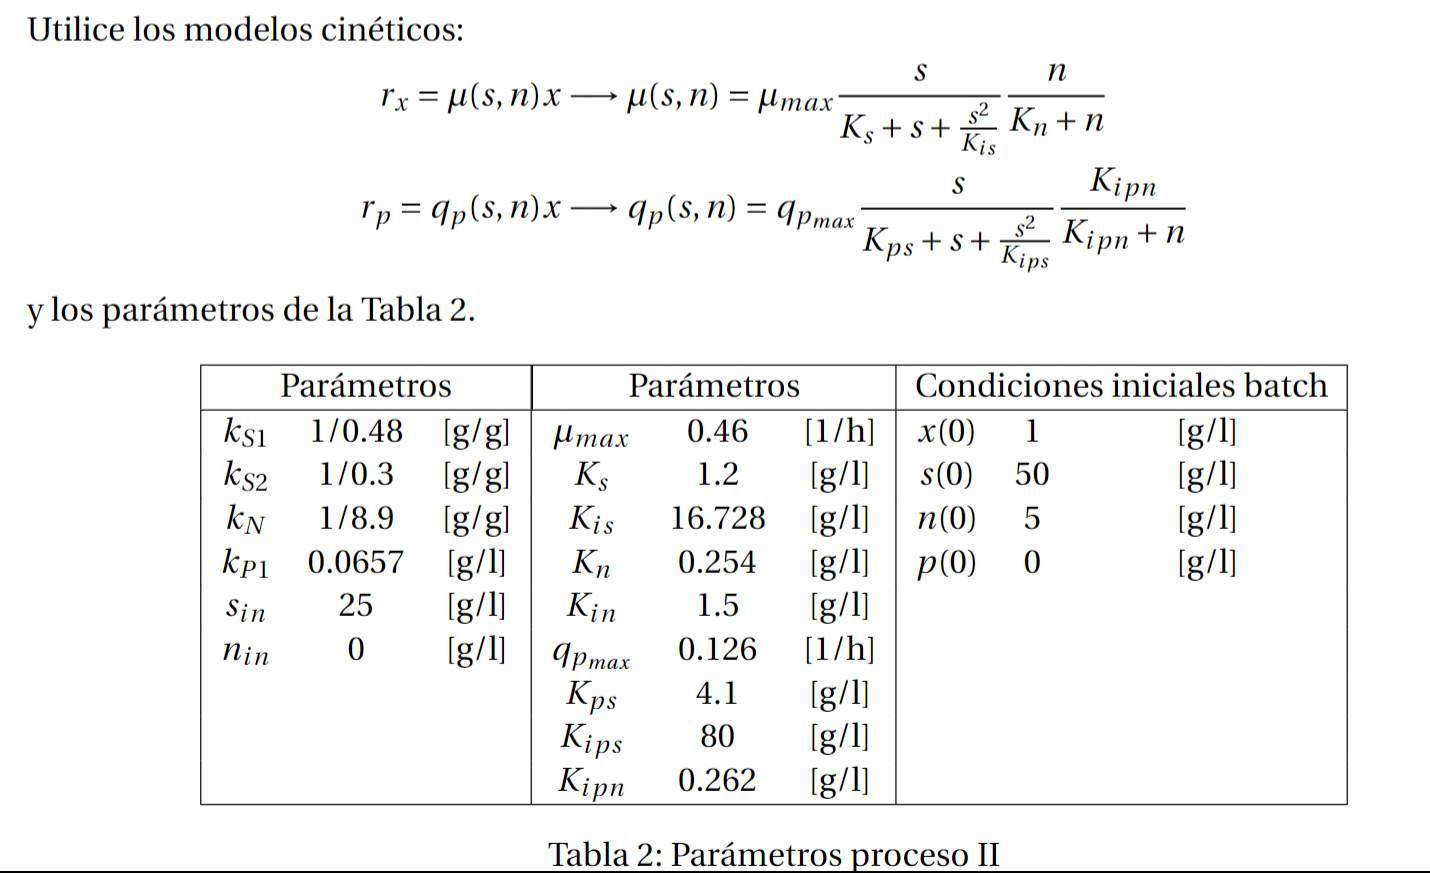

clc; clear all;

## Preguntas

- E

Defino los parámetros del modelo para un batch con modelo de Monod

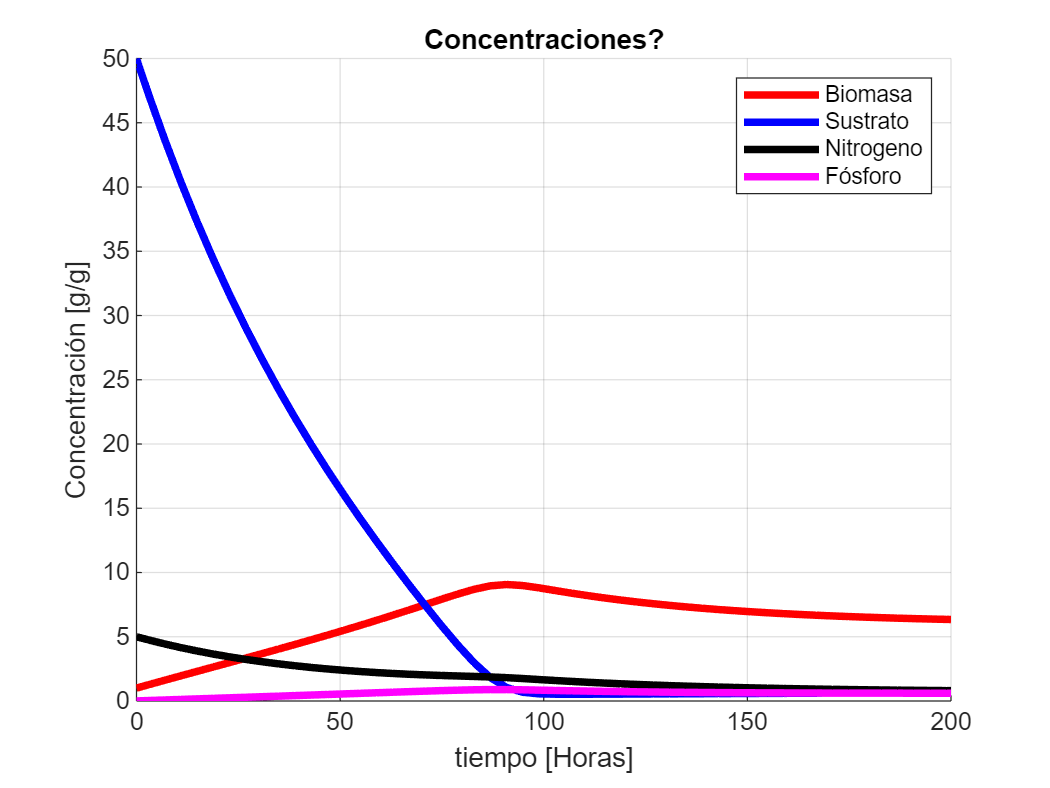

% Datos dados
ks1=1/0.48;
ks2=1/0.3;
kn=1/8.9;
kp1=0.0657;
s_in=25;
n_in=0;
mu_max=0.46;
Ks=1.2;
Kis=16.728;
Kn=0.254;
Kin=1.5;
qp_max=0.126;
Kps=4.1;
Kips=80;
Kipn=0.262;
x0=1;
s0=50;
n0=5;
p0=0;

% Valores de D
Ds=0.01;
Dn=0.01;

% Creamos una estructura para pasar los parámetros al bloque función u
% otros bloques
modelParameters.rx_params.max=mu_max;
modelParameters.rx_params.k1=Ks;
modelParameters.rx_params.k2=Kis;
modelParameters.rx_params.k3=Kn;

modelParameters.rp_params.max=qp_max;
modelParameters.rp_params.k1=Kps;
modelParameters.rp_params.k2=Kips;
modelParameters.rp_params.k3=Kipn;

modelParameters.Kipn=Kipn;
modelParameters.K=[1,0;-ks1,ks2;kn,0;kp1,1];

% Definimos entradas y condiciones iniciales
xi_in=[0,0; s_in,0; 0,n_in; 0,0];
D=[Ds, Dn];
xi0=[x0;s0;n0;p0];
F=[0;0;0;0];
Q=[0;0;0;0];

simConfig.StopTime = "200";
sim_out = sim('TP1\TP1EJ3', simConfig);

% Grafico los resultados de la simulación
time = sim_out.simout.Time;
biomass = reshape(sim_out.simout.Data(1,1,:), size(time));
sustrate = reshape(sim_out.simout.Data(2,1,:), size(time));
nitrogen = reshape(sim_out.simout.Data(3,1,:), size(time));
phosphorus = reshape(sim_out.simout.Data(4,1,:), size(time));

% time_biomass_cero = time(find(sustrate > 0.2095, 1, 'last'));

fig = figure();
hold on; grid on;
title('Concentraciones?')
xlabel('tiempo [Horas]');
ylabel('Concentración [g/g]');
ylim([0 max(sustrate)]);
% xlim([0 time_biomass_cero]);

plot(time, biomass, 'r', 'LineWidth', 3);
plot(time, sustrate, 'b', 'LineWidth', 3);
plot(time, nitrogen, 'k', 'LineWidth', 3);
plot(time, phosphorus, 'm', 'LineWidth', 3);

legend('Biomasa', 'Sustrato', 'Nitrógeno', 'Fósforo');